# **demo14 of Im2mesh package**

demo14 - How to use polyshape object to define geometry for mesh generation

Cite as: Ma, J., & Li, Y. (2025). Im2mesh: A MATLAB/Octave package for generating finite element mesh based on 2D multi-phase image (2.1.5). Zenodo. [https://doi.org/10.5281/zenodo.14847059](https://doi.org/10.5281/zenodo.14847059)

Jiexian Ma, mjx0799@gmail.com. [Project website](https://github.com/mjx888/im2mesh).

## Note

I suggest familiarizing yourself with Im2mesh_GUI before learning Im2mesh package. With graphical user interface, Im2mesh_GUI will help you better understand the workflow and parameters of Im2mesh package.

Im2mesh_GUI: [https://www.mathworks.com/matlabcentral/fileexchange/179684-im2mesh_gui-2d-image-to-finite-element-mesh](https://www.mathworks.com/matlabcentral/fileexchange/179684-im2mesh_gui-2d-image-to-finite-element-mesh)

If you are using Im2mesh package in MATLAB,  you need to install MATLAB Image Processing Toolbox and Mapping Toolbox because Im2mesh package use a few functions in these toolboxes.

## Setup

Before we start, please set folder "Im2mesh_Matlab" as your current folder of MATLAB.

clearvars

Function poly2mesh use a mesh generator called [MESH2D](https://github.com/dengwirda/mesh2d) (developed by Darren Engwirda). We can use the following command to add the folder 'mesh2d-master' to the path of MATLAB. 

addpath(genpath('mesh2d-master'))

## Polyshape

Polyshape is a MATLAB built-in object for polygon-like shapes. We can use object functions of polyshape to create single-part or multi-part geometry. Please refer to the following webpage about object functions of polyshape.

[https://www.mathworks.com/help/matlab/ref/polyshape.html](https://www.mathworks.com/help/matlab/ref/polyshape.html)

## Single-part geometry

### A polyshape

Let's create a polyshape (for a single-part geometry). 

Suppose we want a square with a hole.

% unit square
vertex = [ 0 0; 1 0; 1 1; 0 1 ];
psUnitSq = polyshape(vertex);

Scale the unit square with respect to its centroid to create a tiny square, and rotate.

% scale
[x,y] = centroid(psUnitSq);
refpoint = [x,y];
scale_factor = 0.1;
psSqTiny = scale(psUnitSq, scale_factor, refpoint);

% rotate
[x,y] = centroid(psSqTiny);
refpoint = [x,y];
psSqTiny = rotate(psSqTiny, 45, refpoint);

Perform boolean operation to create a square with a hole.

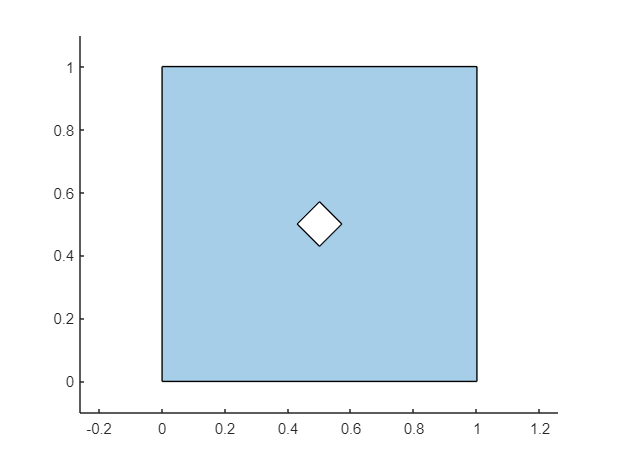

psSqHole = subtract(psUnitSq, psSqTiny);

plot(psSqHole); 
axis equal

### Polygonal boundary

We use function polyshape2bound to convert a cell array of polyshape to a cell array of polygonal boundary. 

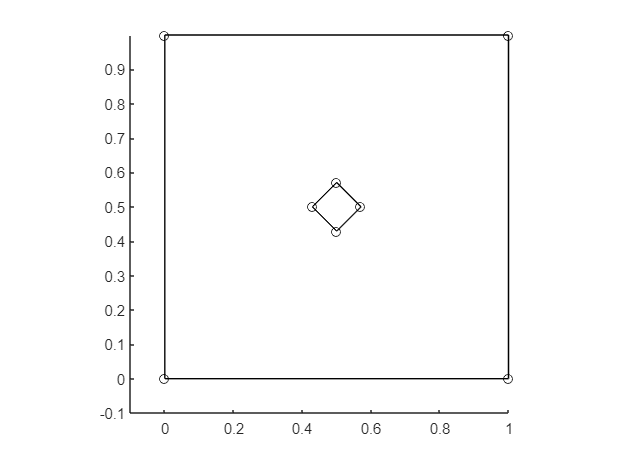

psCell = {psSqHole;psSqTiny}; % psCell is a cell array of polyshape

bounds = polyshape2bound(psCell);

% plot boundaries and show all vertices
plotBounds(bounds,false,'ko-')

### Generate mesh via MESH2D

To generate mesh, we use function poly2mesh.

Note that function poly2mesh uses [MESH2D](https://github.com/dengwirda/mesh2d) (developed by Darren Engwirda) as mesh generator.

[ poly_node, poly_edge ] = getPolyNodeEdge( bounds );

hmax = 500; 
mesh_kind = 'delaunay'; % method used to create mesh size function
grad_limit = 0.1;

option.kind = mesh_kind;    % 'delaunay' or 'delfront' 
                            % default value is 'delaunay'

option.dhdx = grad_limit;   % dhdx is scalar gradient-limit
                            % default +0.2500

[ node, edge, part ] = regroup( poly_node, poly_edge );

[vlfs,tlfs, hlfs] = lfshfn2( node, edge, part, option ) ;

 Refine triangulation...

 -------------------------------------------------------
      |ITER.|          |CDT1(X)|          |CDT2(X)|     
 -------------------------------------------------------
          2                 12                 10
          5                 20                 30



Plot mesh.

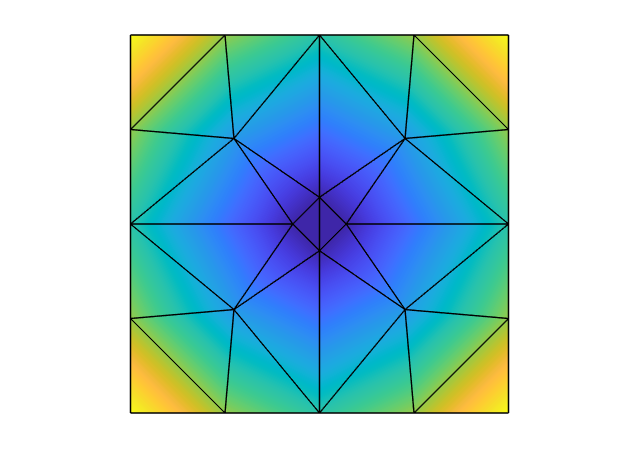

figure;
patch('faces',tlfs(:,1:3),'vertices',vlfs , ...
    'facevertexcdata' , hlfs, ...
    'facecolor','interp') ;
hold on; axis image off;

%---------------------------------------------- extract args
PSLG = edge;

%------------------------------------ calc. "inside" status!
% tnum = zeros(size(tria,+1),+1) ;


ppos = 2;
[stat] = inpoly2( vlfs, node, PSLG(part{ppos},:) );

% for ppos = 1 : length(part)
%    [stat] = inpoly2( vlfs, node, PSLG(part{ppos},:) );
%    tnum(stat)  = ppos ;
% end

hlfs2 = hlfs;
scale = 0.3;
hlfs2( stat ) = hlfs2( stat ) * scale;

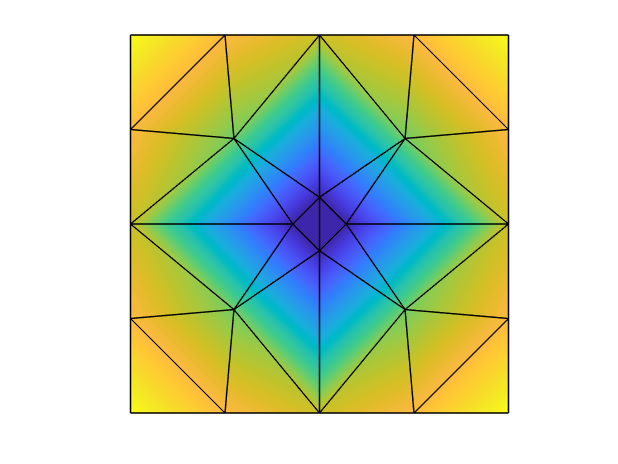

figure;
patch('faces',tlfs(:,1:3),'vertices',vlfs , ...
    'facevertexcdata' , hlfs2, ...
    'facecolor','interp') ;
hold on; axis image off;

hlfs2 = min(hmax,hlfs2) ;

[slfs] = idxtri2(vlfs,tlfs) ;

%---------------------------------------------- do mesh-gen.
hfun = @trihfn2;

[vert,etri,tria,tnum] = refine2(node,edge,part,[],hfun, ...
                                vlfs,tlfs,slfs,hlfs2);

 Refine triangulation...

 -------------------------------------------------------
      |ITER.|          |CDT1(X)|          |CDT2(X)|     
 -------------------------------------------------------
          4                 40                 10
         10                 40                258
         17                 40                314



%---------------------------------------------- do mesh-opt.
% SMOOTH2 routine provides iterative mesh "smoothing" capabilities, 
% seeking to improve triangulation quality by adjusting the vertex 
% positions and mesh topology.

[vert,etri,tria,tnum] = smooth2(vert,etri,tria,tnum);

 Smooth triangulation...

 -------------------------------------------------------
      |ITER.|          |MOVE(X)|          |DTRI(X)|     
 -------------------------------------------------------
          4                117                312
          8                 31                312



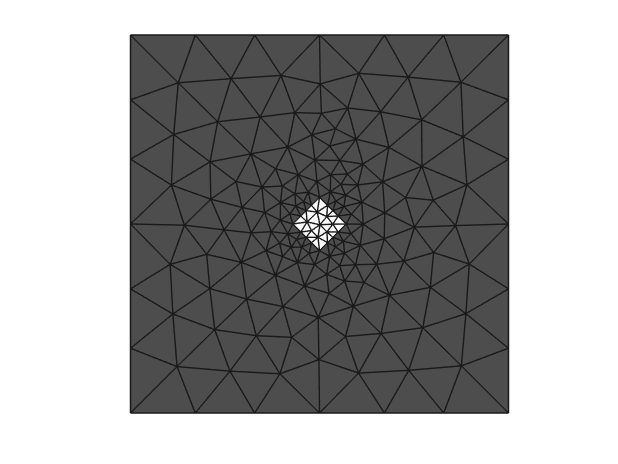

plotMeshes(vert,tria,tnum);